% 1. create the simulation name and the folder to save all simulated
% samples and parameters

% give this simulation a name
SimulationName='simulation_HybridDetectorTest_20231218';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/simulation_HybridDetectorTest_20231218/'

cd(filepath)

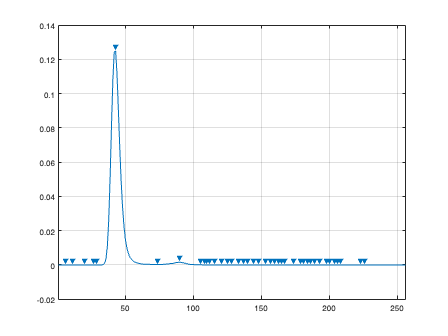

% 2. load prf, calculate the full width half maximum of the prf; use the FWHM to
% generate a corresponding gaussian PRF for PMT simulation

PrfName_original = 'prf_InsightBottomGreen_20231017.mat';

load(PrfName_original)
figure
findpeaks(prf)

[pks, locs, width, p] = findpeaks(prf); % Derive the peak location and the FWHM of the PRF curve
width(6)*(12.5/256) % The main peak of the PRF is the 6th peak. This is the FWHM of experimental collected PRF

ans = 0.3423

gaussian_sigma = (width(6)*(12.5/256))/2.355 % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355

gaussian_sigma = 0.1453

gaussian_miu = locs(6) * (12.5/256) % Guassian distributio mean same as the peak location

gaussian_miu = 2.0996

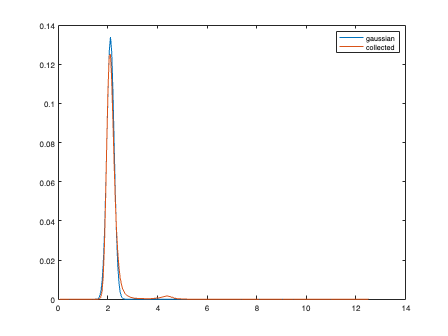


gaussian_x = (1:1:256)*(12.5/256); % Create x axis
gaussian_y = 1/(gaussian_sigma*sqrt(2*pi))*exp(-(gaussian_x-gaussian_miu).^2/(2*gaussian_sigma^2)); % Calculate y axis of the Gaussian distribution
gaussian_y = gaussian_y/sum(gaussian_y); % Normalize the Gaussian distribution with sum being 1

% Plot the experimental PRF and the Gaussian PRF to compare
figure
plot(gaussian_x, gaussian_y)
hold on
plot(gaussian_x, prf)
legend('gaussian', 'collected')
hold off


% Save the PRF file under a name
prf = gaussian_y;
PrfName_PMT = 'Prf_gaussion_PMT.mat';
save(PrfName_PMT, 'prf')
PRF_PMT = prf;
PRF_PMT_norm = PRF_PMT/max(PRF_PMT);


% 3. create a Gaussian PRF  hybrid detector (HBD) prf
HBD_width = 120/1000 % 120 ps accroding to BH website https://www.becker-hickl.com/products/hybrid-photo-detectors/

HBD_width = 0.1200

HBD_sigma = (HBD_width)/2.355 % for normal distribution, FWHM = 2*sqrt(2*ln2)*sigma = 2.355*sigma; so sigma = FWHM/2.355

HBD_sigma = 0.0510

HBD_miu = locs(6) * (12.5/256) % Guassian distributio mean same as the peak location

HBD_miu = 2.0996

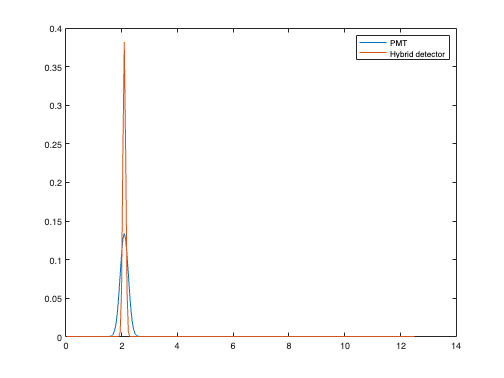


HBD_x = (1:1:256)*(12.5/256); % Create x axis
HBD_y = 1/(HBD_sigma*sqrt(2*pi))*exp(-(HBD_x-HBD_miu).^2/(2*HBD_sigma^2));  % Calculate y axis of the Gaussian distribution
HBD_y = HBD_y/sum(HBD_y); % Guassian distributio mean same as the peak location

% plot the PRF for PMT and HBD together to compare
figure
plot(gaussian_x, gaussian_y)
hold on
plot(gaussian_x, HBD_y)
legend('PMT', 'Hybrid detector')
hold off


% save the PRF under a file
prf = HBD_y

prf =          0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0061    0.0609    0.2415    0.3823    0.2415    0.0609    0.0061    0.0002    0.0000    0.0000    0.0000


PrfName_HBD = 'Prf_gaussion_HBD.mat';
save(PrfName_HBD, 'prf')
PRF_HBD = prf;
PRF_HBD_norm = PRF_HBD/max(PRF_HBD);


fit_range = [10 235]

fit_range =     10   235


CalcEmpLft(fit_range, PRF_PMT)

ans = 1.6602

CalcEmpLft(fit_range, PRF_HBD)

ans = 1.6602

% 4. define the double exponential decay parameters and other parameters in
% the simulation

p1_samples=0.4:0.01:0.6; % simulate the p1 range
tau1=2.14; % tau1
tau2=0.69; % tau2
DC=0; % dark count = 0 because DC is included in autofluorescence collection

afterpulse_ratio_PMT=0.0032; % afterpulse ratio for PMT conditions
afterpulse_ratio_HBD=0;

SS_samples=100000:50000:800000; % simulated sample size range.

PopulationName_prefix = 'Simulation_AfterRivisingFunctions_20231201';

mkdir('Simulated_data')

% 6. The script for batch processing
% This is the content of the script for batch processing.
% use batch function for parallel computing of simulation

    p1=p1_samples(i); % define p1
    p2=1-p1;
    n_sensor_PMT_simulated = {};
    n_sensor_HBD_simulated = {};
    PopulationName=[PopulationName_prefix,'_FLP_population_',num2str(p1),'.mat']; % define double exponential population name
%     GenPop512_FLIM_v2(1000000, p1, p2, tau1, tau2, PopulationName);  % generate the double exponential population
    parfor j=1:length(SS_samples)
        rng('shuffle','twister') % added to shuffle the random number generator
        SS=SS_samples(j); % define the sensor sample size
        n_PMT_all = zeros(500, 256);
        n_HBD_all = zeros(500, 256);
        for k=1:500 % simulating 200 times
            [n1, n2, n_PMT] = FLIMsim512_FLIM_v2(SS,PrfName1, PopulationName); % simulation with afterpulse 0
            n_PMT_all(k, :) = n_PMT;

            [n1, n2, n_HBD] = FLIMsim512_FLIM_v2(SS,PrfName2, PopulationName);
            n_HBD_all(k, :) = n_HBD;
        end
        n_sensor_PMT_simulated{j} = n_PMT_all;
        n_sensor_HBD_simulated{j} = n_HBD_all;

    end

    simulated_name_PMT = ['Simulated_data/', num2str(p1), '_PMT_sensor.mat'];
    save(simulated_name_PMT, 'n_sensor_PMT_simulated')

    simulated_name_HBD = ['Simulated_data/', num2str(p1), '_HBD_sensor.mat'];
    save(simulated_name_HBD, 'n_sensor_HBD_simulated')


% 6. create the batch processing script, copy and paste the script above into the script and save it under the root folder of the simulation
edit Simulation_sensor_batch_20231204

% 7. call the local cluster
c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-MBP
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

% 8. batch processing of simulation, each p1 condition runs on one worker.
for i=18:21%length(p1_samples) % for each p1 value, run the script parallelly
    batch('Simulation_sensor_batch_20231204','pool',3)
end

ans = 

 Job

    Properties: 

                   ID: 13
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 04-Dec-2023 23:50:13
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [4 4]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% 6. create the batch processing script, copy and paste the script above into the script and save it under the root folder of the simulation
edit Simulation_autoF_batch_20231204

load('Autofluo_fitting_parameters')

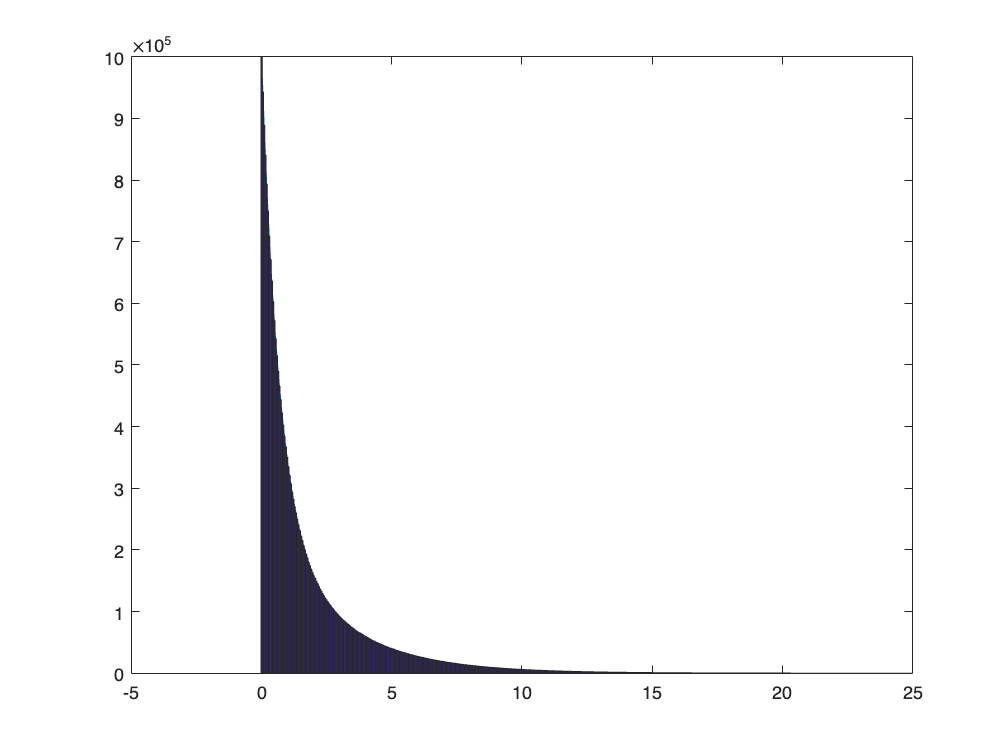

    24736350



PopulationName_autoF= 'AutofluorescencePopulation_fromFitting.mat'; % define double exponential population name
GenPop512_FLIM_v2(1000000, p1_auto, p2_auto, tau1_auto, tau2_auto, PopulationName_autoF); % generate the autofluorescence population

    SS=SS_samples(j);
    n_auto_PMT_all = zeros(500, 256);
    n_auto_HBD_all = zeros(500, 256);
    for i=1:500
        rng('shuffle','twister')
        AF=(randi(round(AF_mean_corrected*0.1)))+round(AF_mean_corrected*0.95); % 10% of fluctuatio
        [n1, n2, n_auto_PMT] = FLIMsim512_FLIM_v2(AF,PrfName1, PopulationName_autoF);
        n_auto_PMT_all(i, :) = n_auto_PMT;

        [n1, n2, n_auto_HBD] = FLIMsim512_FLIM_v2(AF,PrfName2, PopulationName_autoF);
        n_auto_HBD_all(i, :) = n_auto_HBD;

    end
    autoF_save_name_PMT = ['autoF_PMT_', num2str(SS), '.mat'];
    save(autoF_save_name_PMT, 'n_auto_PMT_all')

    autoF_save_name_HBD = ['autoF_HBD_', num2str(SS), '.mat'];
    save(autoF_save_name_HBD, 'n_auto_HBD_all')

% 7. call the local cluster
c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

% 8. batch processing of simulation, each p1 condition runs on one worker.
for i=1length(SS_samples) % for each p1 value, run the script parallelly
    batch('Simulation_autoF_batch_20231204','pool',3)
end

% 14.  this is to create the distribution of background and testing the simulation of the backgroud from autofluorescence
% fitting
bkgrd_AP_distribution = zeros(1, 256) + 1/251; 
bkgrd_AP_distribution([1,2,3,4,256]) = 0; % background evenly distributed over time, but channel 1-4 and 256 as 0
bkgrd_AP_sum = round(autofluo_bkgrd*251); % background total number
% AutoFluo_sim(bkgrd_AP_distribution, bkgrd_AP_sum, 'bkgrd_AP_test.mat') % testing of simulation

% 16. the script for batch processing of simulation of background
% in Bkgrd_AP_simulation_20231113.m:

    SS=SS_samples(j);
    n_bkgrd_all = zeros(500, 256)
    for i=1:500
        rng('shuffle','twister')
        Bkgrd_AP=(randi(round(bkgrd_AP_sum*0.1)))+round(bkgrd_AP_sum*0.95); % 10% of fluctuation
        Bkgrd_SensorAP = Bkgrd_AP;
        [n_bkgrd] = AutoFluo_sim_v2(bkgrd_AP_distribution, Bkgrd_SensorAP);
        n_bkgrd_all(i, :) = n_bkgrd;
    end

    bkgrd_save_name = ['Simulated_data/bkgrd_AP_HBD_', num2str(SS), '.mat'];
    save(bkgrd_save_name, 'n_bkgrd_all')

% 15. create the folder and script for bactch processin of simulation of background
% and the afterpulse of the sensor fluorescence

edit Bkgrd_AP_simulation_20231204.m

% 17. call the local cluster
c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-mbp
                NumWorkers: 21
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

% 18. batch processing of simulation of background
for j=1:length(SS_samples)
    batch('Bkgrd_AP_simulation_20231204','pool',4)
end

ans = 

 Job

    Properties: 

                   ID: 17
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:39:50
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 18
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:40:07
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 19
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:40:30
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 20
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:41:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 21
                 Type: pool
             Username: pingchuanma
                State: queued
       SubmitDateTime: 06-Dec-2023 10:43:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 22
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:44:32
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 23
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:45:53
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 24
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:47:00
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 25
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:48:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 26
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:50:38
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 27
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:51:19
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 28
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:53:09
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 29
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:54:06
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 30
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:55:47
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ans = 

 Job

    Properties: 

                   ID: 31
                 Type: pool
             Username: pingchuanma
                State: running
       SubmitDateTime: 06-Dec-2023 10:57:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
      NumWorkersRange: [5 5]
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

% Fitting for PMT conditions

ch = 1; % only for FLIM channel 1
PrfName_PMT = 'Prf_gaussion_PMT.mat';
load(PrfName_PMT)
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (12.5/256)*1000;


for i = 1:length(p1_samples) % each p1 condition

    p1=p1_samples(i); % define p1
    simulated_name = ['/Volumes/PcSSDA/Simulated_data/', num2str(p1), '_PMT_sensor.mat'];
    load(simulated_name)

    %%%%%
    % save the fitting parameters
    p1_fitted = zeros(500, length(SS_samples));  % fitted p1
    tau_avg = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve calculated to infinite
    tau_avgTrunc = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve within fitting range
    tau_empTrunc = zeros(500, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    chi2 = zeros(500, length(SS_samples)); % chi square from fitting
    beta6 = zeros(500, length(SS_samples)); % SHG term from fitting
    backcorr = zeros(500, length(SS_samples)); % background term from fitting

    for j = 1:length(SS_samples) % each sample size condition

        SS = SS_samples(j);

        autoF_simulated_name = ['/Volumes/PcSSDA/Simulated_data/autoF_PMT_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        bkgrd_simulated_name = ['/Volumes/PcSSDA/Simulated_data/bkgrd_AP_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        for k = 1:500 % 200 repeats of simulation

            % load simulated sample n

            spc.lifetimes{1} = n_sensor_PMT_simulated{j}(k,:) + n_auto_PMT_all(k, :) + n_bkgrd_all(k, :); % assign the value to spc.lifetimes for fitting

            % initiate the fitting parameters
            
            spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
            spc.fits{1}.beta3 = 10000;
            spc.fits{1}.beta5 = 0; % delta peak time and SHG as 0
            spc.fits{1}.beta6 = 0;

            spc_fitexp2prfGY(ch); % fitting
            spc_adjustTauOffset(ch); 


            % collect parameters after fitting
            p1_fitted(k,j)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
            tau_avg(k,j)=spc.fits{ch}.avgTau; 
            tau_avgTrunc(k,j)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k,j)=spc.fits{ch}.EmpTauTrunc;
            chi2(k,j)=spc.fits{ch}.redchisq;
            beta6(k,j)=spc.fits{ch}.beta6;
            backcorr(k,j)=spc.fits{ch}.backCorr;

            
        end
    end

    % save the fitting parameters for each p1 conditon
    savename = ['Results_20231217_PMT_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_avg','tau_avgTrunc','tau_empTrunc','chi2','beta6','backcorr')


    
end

% Fitting for HBD conditions

ch = 1; % only for FLIM channel 1
PrfName_HBD = 'Prf_gaussion_HBD.mat';
load(PrfName_HBD)
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (12.5/256)*1000;

for i = 1:length(p1_samples) % each p1 condition

    p1=p1_samples(i); % define p1
    simulated_name = ['/Volumes/PcSSDA/Simulated_data/', num2str(p1), '_HBD_sensor.mat'];
    load(simulated_name)

    %%%%%
    % save the fitting parameters
    p1_fitted = zeros(500, length(SS_samples));  % fitted p1
    tau_avg = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve calculated to infinite
    tau_avgTrunc = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve within fitting range
    tau_empTrunc = zeros(500, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    chi2 = zeros(500, length(SS_samples)); % chi square from fitting
    beta6 = zeros(500, length(SS_samples)); % SHG term from fitting
    backcorr = zeros(500, length(SS_samples)); % background term from fitting

    for j = 1:length(SS_samples) % each sample size condition

        SS = SS_samples(j);

        autoF_simulated_name = ['/Volumes/PcSSDA/Simulated_data/autoF_HBD_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        bkgrd_simulated_name = ['/Volumes/PcSSDA/Simulated_data/bkgrd_AP_HBD_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        for k = 1:500 % 200 repeats of simulation

            % load simulated sample n

            spc.lifetimes{1} = n_sensor_HBD_simulated{j}(k,:) + n_auto_HBD_all(k, :) + n_bkgrd_all(k, :); % assign the value to spc.lifetimes for fitting

            % initiate the fitting parameters
            
            spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
            spc.fits{1}.beta3 = 10000;
            spc.fits{1}.beta5 = 0; % delta peak time and SHG as 0
            spc.fits{1}.beta6 = 0;

            spc_fitexp2prfGY(ch); % fitting
            spc_adjustTauOffset(ch); 


            % collect parameters after fitting
            p1_fitted(k,j)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
            tau_avg(k,j)=spc.fits{ch}.avgTau; 
            tau_avgTrunc(k,j)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k,j)=spc.fits{ch}.EmpTauTrunc;
            chi2(k,j)=spc.fits{ch}.redchisq;
            beta6(k,j)=spc.fits{ch}.beta6;
            backcorr(k,j)=spc.fits{ch}.backCorr;

            
        end
    end

    % save the fitting parameters for each p1 conditon
    savename = ['Results_20231217_HBD_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_avg','tau_avgTrunc','tau_empTrunc','chi2','beta6','backcorr')


    
end

fit_range = [10 235];

% P1 and sensor photon number conditions for the simulation
p1_samples = 0.4:0.01:0.6;
SS_samples = 100000:50000:800000;

% Initialize the mean and standard deviation variable
tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

% Initialize the variable to save the calculated empirical lifetime for each simulated data
tau_all = {};

for i = 1:length(p1_samples) % each p1 condition

    p1=p1_samples(i); % define p1
    simulated_name = ['Simulated_data/', num2str(p1), '_HBD_sensor.mat'];
    load(simulated_name)

    for j = 1:length(SS_samples) % each sample size condition

        SS = SS_samples(j);

        autoF_simulated_name = ['Simulated_data/autoF_HBD_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        bkgrd_simulated_name = ['Simulated_data/bkgrd_AP_HBD_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        EmpLft = zeros(1, 500);

        for k = 1:500

            n_final_HBD = n_sensor_HBD_simulated{j}(k,:) + n_auto_HBD_all(k, :) + n_bkgrd_all(k, :); % assign the value to spc.lifetimes for fitting
    
            EmpLft(k) = CalcEmpLft(fit_range, n_final_HBD);

        end

        tau_mean_all(j,i) = mean(EmpLft);
        tau_std_all(j,i) = std(EmpLft);
        tau_all{j,i} = EmpLft;

    end

end

save('Tau_HBD.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')




fit_range = [10 235];

% P1 and sensor photon number conditions for the simulation
p1_samples = 0.4:0.01:0.6;
SS_samples = 100000:50000:800000;

% Initialize the mean and standard deviation variable
tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

% Initialize the variable to save the calculated empirical lifetime for each simulated data
tau_all = {};

for i = 1:length(p1_samples) % each p1 condition

    p1=p1_samples(i); % define p1
    simulated_name = ['Simulated_data/', num2str(p1), '_PMT_sensor.mat'];
    load(simulated_name)

    for j = 1:length(SS_samples) % each sample size condition

        SS = SS_samples(j);

        autoF_simulated_name = ['Simulated_data/autoF_PMT_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        bkgrd_simulated_name = ['Simulated_data/bkgrd_AP_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        EmpLft = zeros(1, 500);

        for k = 1:500

            n_final_HBD = n_sensor_PMT_simulated{j}(k,:) + n_auto_PMT_all(k, :) + n_bkgrd_all(k, :); % assign the value to spc.lifetimes for fitting
    
            EmpLft(k) = CalcEmpLft(fit_range, n_final_HBD);

        end

        tau_mean_all(j,i) = mean(EmpLft);
        tau_std_all(j,i) = std(EmpLft);
        tau_all{j,i} = EmpLft;

    end

end

save('Tau_PMT.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')


% savename_postfix = 'Results_20231217_PMT_';
savename_postfix = 'Results_20231217_HBD_';


% initialize the calculated p1, tau, and chi2 matrix
p1_mean_all = zeros(length(SS_samples), length(p1_samples));
p1_std_all = zeros(length(SS_samples), length(p1_samples));

tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

chi2_mean_all = zeros(length(SS_samples), length(p1_samples));
chi2_std_all = zeros(length(SS_samples), length(p1_samples));



for i = 1:length(p1_samples)
    p1=p1_samples(i);
    savename = ['/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/simulation_HybridDetectorTest_20231204/',savename_postfix, num2str(i), '.mat']; 
    load(savename) % for each p1 condition, load the saved file, calculate the p1 and mean
    for j = 1:length(SS_samples)
        p1_mean_all(j,i) = mean(p1_fitted(:,j)); % mean p1
        p1_std_all(j,i) = std(p1_fitted(:,j)); % std p1

        tau_mean_all(j,i) = mean(tau_empTrunc(:,j)); % mean lifetime
        tau_std_all(j,i) = std(tau_empTrunc(:,j));% std lifetime

        chi2_mean_all(j,i) = mean(chi2(:,j)); % mean chi square
        chi2_std_all(j,i) = std(chi2(:,j)); % std chi square

    end
end


% 5. for heatmap, construct the labels for x and y axis
x_labels_p1 = {};
for i = 1:length(p1_samples)
    if mod(i,3) == 1
        x_labels_p1{i} = num2str(p1_samples(i));
    else
        x_labels_p1{i} = ' ';
    end
end

y_labels_SS = {};
for i = 1:length(SS_samples)
    if mod(i,4) == 1
        y_labels_SS{i} = num2str(SS_samples(i)/10000);
    else
        y_labels_SS{i} = ' ';
    end
end

% 6. plot the heatmap of fitted p1 and empirical lifetime
figure
h = heatmap(p1_mean_all, 'ColorLimits', [0.375 0.625])

h =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {15×1 cell}
    ColorData: [15×21 double]

  Show all properties


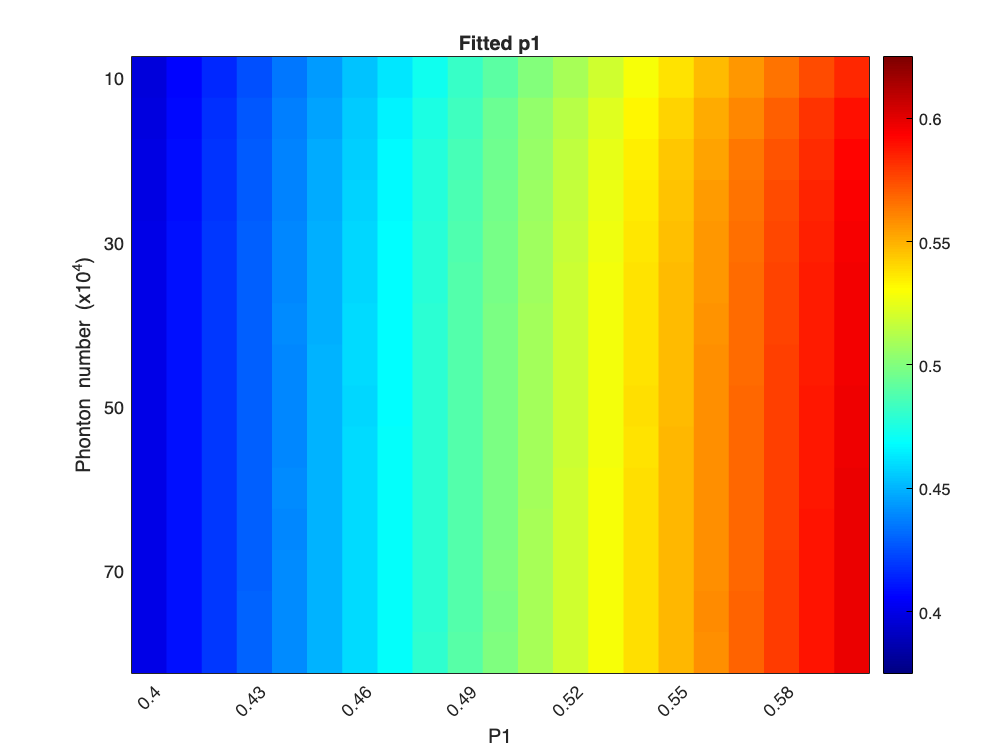

grid off
% colormap parula
colormap jet
h.Title = 'Fitted p1';
h.XLabel = 'P1';
h.YLabel = 'Phonton number (x10^4)';
h.XDisplayLabels = x_labels_p1;
h.YDisplayLabels = y_labels_SS;



figure
h = heatmap(tau_mean_all, 'ColorLimits', [3.35 3.65])

h =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {15×1 cell}
    ColorData: [15×21 double]

  Show all properties


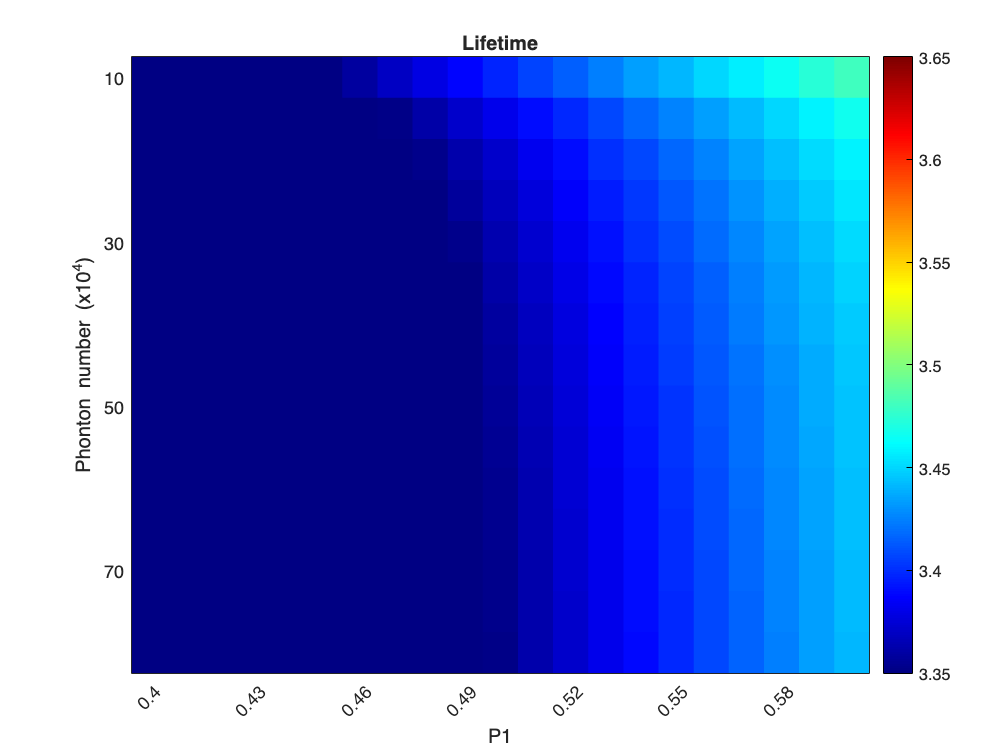

grid off
colormap jet
% colormap parula
h.Title = 'Lifetime';
h.XLabel = 'P1';
h.YLabel = 'Phonton number (x10^4)';
h.XDisplayLabels = x_labels_p1;
h.YDisplayLabels = y_labels_SS;

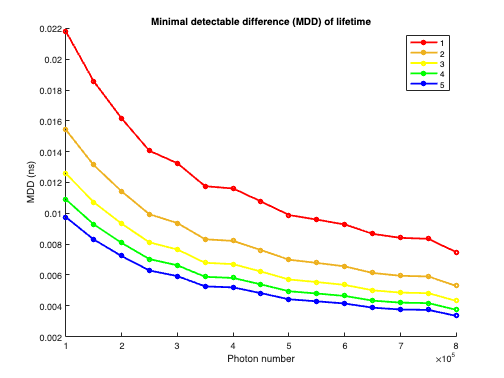

% 1. calculate the minimal detectable difference with average std under a
% certain photon count condition
load('Tau_HBD.mat')
% load('Tau_PMT.mat')

% tau_std_mean_SS = zeros(1, length(SS_samples)); % initializing the mean standard deviation vector
tau_MDD_SS = zeros(1, length(SS_samples)); % initializing the minimal detectable difference vector
tau_MDD_SS_plot = []; % collecting the MDD vectors under each photon count condition
Colors = {'red', [0.9290 0.6940 0.1250], 'yellow', 'green', 'blue'};
legends = {'1', '2', '3', '4', '5'};
p1_plot = 0.5;

figure

for n_samples = 1:5 % assuming there are 1 or 2 or ... or 5 pairs of sampling for real experiments

%     for i = 1: length(SS_samples)
%         
%         tau_std_mean_SS(i) = mean(tau_std_all(i,:)); % the mean standard deviation under each photon number condition
%     end

%     tau_MDD_SS = tau_std_mean_SS*3.96/sqrt(n_samples); % calculate the MDD

    tau_std = tau_std_all(:,find(p1_samples == p1_plot));
    tau_MDD_SS = tau_std*3.96/sqrt(n_samples);
    eval(['tau_MDD_SS', '_', num2str(n_samples), '=tau_MDD_SS;'])

    tau_MDD_SS_plot = [tau_MDD_SS_plot tau_MDD_SS];% collecting the MDD vectors under each photon count condition
    plot(SS_samples,tau_MDD_SS, '-o','MarkerSize', 4, 'LineWidth', 2, 'Color', Colors{n_samples})
    hold on
end

legend(legends)
title('Minimal detectable difference (MDD) of lifetime')
xlabel('Photon number')
ylabel('MDD (ns)')
box off

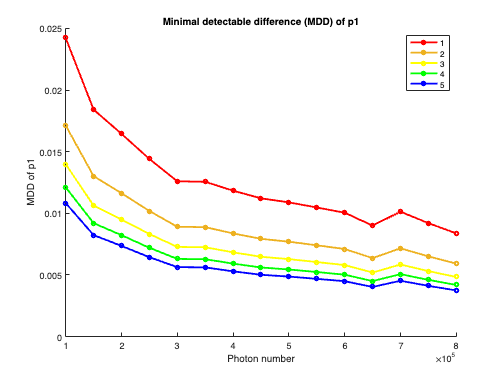

% 2. Calculate the minimal detectable difference with average std under a
% certain photon count condition;
% The process is same as what's for tau but instead use the fitted p1.

% p1_std_mean_SS = zeros(1, length(SS_samples));
p1_MDD_SS = zeros(1, length(SS_samples));
p1_MDD_SS_plot = [];
Colors = {'red', [0.9290 0.6940 0.1250], 'yellow', 'green', 'blue'};
legends = {'1', '2', '3', '4', '5'};
p1_plot = 0.5;

figure

for n_samples = 1:5

%     for i = 1: length(SS_samples)
%         
%         p1_std_mean_SS(i) = mean(p1_std_all(i,:));
%     end
%     p1_MDD_SS = p1_std_mean_SS*3.96/sqrt(n_samples);

    p1_std = transpose(p1_std_all(:,find(p1_samples == p1_plot)));
    p1_MDD_SS = p1_std*3.96/sqrt(n_samples);
    eval(['p1_MDD_SS', '_', num2str(n_samples), '=p1_MDD_SS;'])

%     scatter(SS_samples,tau_MDD_SS, 30, 'filled', 'MarkerFaceColor', Colors{n_samples})
%     hold on
    p1_MDD_SS_plot = [p1_MDD_SS_plot; p1_MDD_SS];
    plot(SS_samples,p1_MDD_SS, '-o','MarkerSize', 4, 'LineWidth', 2, 'Color', Colors{n_samples})
    hold on
end

legend(legends)
title('Minimal detectable difference (MDD) of p1')
xlabel('Photon number')
ylabel('MDD of p1')
box off

% Generate example histograms for two PRF conditions
load('Simulated_data/0.5_PMT_sensor.mat')
load('Simulated_data/autoF_PMT_500000.mat')
load('Simulated_data/bkgrd_AP_500000.mat')

lifetime_histogram_PMT = n_sensor_PMT_simulated{9}(1,:) + n_auto_PMT_all(1,:) + n_bkgrd_all(1,:);

load('Simulated_data/0.5_HBD_sensor.mat')
load('Simulated_data/autoF_HBD_500000.mat')
load('Simulated_data/bkgrd_AP_HBD_500000.mat')

lifetime_histogram_HBD = n_sensor_HBD_simulated{9}(1,:) + n_auto_HBD_all(1,:) + n_bkgrd_all(1,:);


% The next twp sections are for running the statistical t test on the fitted
% p1 and empirical lifetime between PMT and HBD conditions
savename_postfix = {};

p1_fitted_test05 = {};
tau_test05 = {};

savename_postfix{1} = 'Results_20231217_PMT_';
savename_postfix{2} = 'Results_20231217_HBD_';

i = 11;
for j = 1:2
    savename = [savename_postfix{j}, num2str(i), '.mat'];
    load(savename)
    p1_fitted_test05{j} = p1_fitted;
    tau_test05{j} = tau_empTrunc;
end

t_test_p1 = {};
t_test_tau = {};
for j = 1
    t_test_p1{j} = zeros(1,15);
    t_test_tau{j} = zeros(1,15);
end

comparisons = {[1 2]};

for j = 1
    for i = 1:15
        t_test_p1{j}(i) = 15*ranksum(p1_fitted_test05{comparisons{j}(1)}(:,i), p1_fitted_test05{comparisons{j}(2)}(:,i));
        t_test_tau{j}(i) = 15*ranksum(tau_test05{comparisons{j}(1)}(:,i), tau_test05{comparisons{j}(2)}(:,i));
    end
end

Withinp1_t_test_PMT = zeros(1, 14);
Withinp1_t_test_HBD = zeros(1, 14);
Withintau_t_test_PMT = zeros(1, 14);
Withintau_t_test_HBD = zeros(1, 14);

for i = 1:14
    Withinp1_t_test_PMT(i) = ranksum(p1_fitted_test05{1}(:,i), p1_fitted_test05{1}(:,15));
end

for i = 1:14
    Withinp1_t_test_HBD(i) = ranksum(p1_fitted_test05{2}(:,i), p1_fitted_test05{2}(:,15));
end

for i = 1:14
    Withintau_t_test_PMT(i) = ranksum(tau_test05{1}(:,i), tau_test05{1}(:,15));
end

for i = 1:14
    Withintau_t_test_HBD(i) = ranksum(tau_test05{2}(:,i), tau_test05{2}(:,15));
end

function EmpLft = CalcEmpLft(range, n)

x_axis = (1:1:(range(2)-range(1)+1))*(12.5/256);
EmpLft = sum(n(range(1):range(2)).*x_axis)/sum(n(range(1):range(2)));

end